|================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        NumHL |   Layer1Size |   Layer2Size |   Layer3Size | InitialLearn-|    TrainFcn1 |    TrainFcn2 |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              | Rate         |              |              |
|================================================================================================================================================================================|
|    1 | Best   |  2.2204e-16 |      27.398 |  2.2204e-16 |  2.2204e-16 |            3 |           36 |           47 |           28 |    0.0035183 |      satlins |      satlins |
|    2 | Accept |  2.2204e-16 |      1.9804 |  2.2204e-16 |  2.2204e-16 |            2 |           23 |  

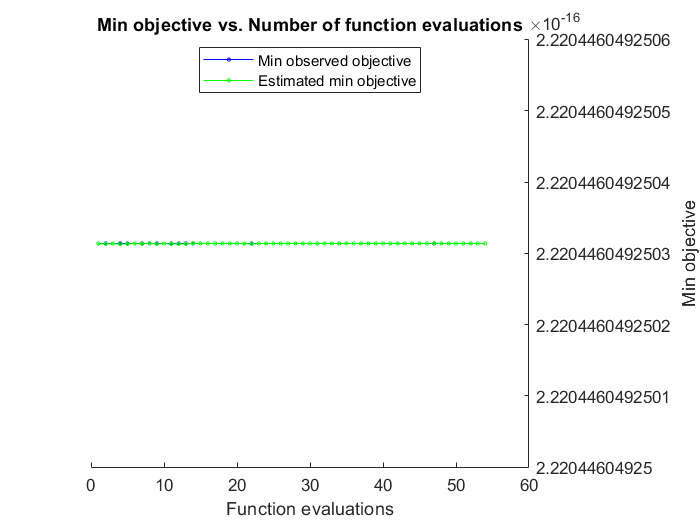


__________________________________________________________
Optimization completed.
MaxTime of 900 seconds reached.
Total function evaluations: 54
Total elapsed time: 906.0478 seconds
Total objective function evaluation time: 842.4873

Best observed feasible point:
    NumHL    Layer1Size    Layer2Size    Layer3Size    InitialLearnRate    TrainFcn1    TrainFcn2
    _____    __________    __________    __________    ________________    _________    _________

      3          36            47            28           0.0035183         satlins      satlins 

Observed objective function value = 2.2204e-16
Estimated objective function value = 2.2204e-16
Function evaluation time = 27.3976

Best estimated feasible point (according to models):
    NumH

%Parameters
Inputs = Predictors;
Targets = double(Response);
% XVal = XValid;
% YVal = YValid; 
% Xtes = XTest;
% Ytes = YTest;


%Setting up hyperparameters that need to be optimized 

minHiddenLayerSize = 4;
maxHiddenLayerSize = 50;
hiddenLayerSizeRange = [minHiddenLayerSize maxHiddenLayerSize];
optimVars = [optimizableVariable('NumHL', [2 3],'Type','integer')
             optimizableVariable('Layer1Size',hiddenLayerSizeRange,'Type','integer')
             optimizableVariable('Layer2Size',hiddenLayerSizeRange,'Type','integer')
             optimizableVariable('Layer3Size',hiddenLayerSizeRange,'Type','integer')
             %optimizableVariable('TrainFcn0', {'trainlm' 'trainbr' 'trainbfg' 'traincgb' 'traincgf' 'traingd' 'traingda' 'traingdm' 'traingdx' 'trainoss' 'trainrp' 'trainscg' 'trainb' 'trains'},'Type','categorical')               
             %optimizableVariable('nEpochs',[50 2000],'Type','integer')
             optimizableVariable('InitialLearnRate',[1e-3 1],'Transform','log')
             %optimizableVariable('Momentum',[0.5 0.98])
             optimizableVariable('TrainFcn1',{'logsig' 'tansig' 'satlins' ...
             'purelin' 'poslin' 'satlin' 'compet' 'elliotsig' 'hardlim'...
             'hardlims' 'netinv' 'radbas' 'radbasn' 'softmax' 'tribas'},'Type','categorical')
             optimizableVariable('TrainFcn2',{'logsig' 'tansig' 'satlins' ...
             'purelin' 'poslin' 'satlin' 'compet' 'elliotsig' 'hardlim'...
             'hardlims' 'netinv' 'radbas' 'radbasn' 'softmax' 'tribas'},'Type','categorical')
             ];
        
%Bayesion Optimization

%ObjFcn = makeObjFcn(Inputs, Targets, XVal, YVal, Xtes, Ytes);
ObjFcn = makeObjFcn(Inputs, Targets);
BayesObject = bayesopt(ObjFcn,optimVars,...
    'MaxObj',300,...
    'MaxTime',15*60,...
    'IsObjectiveDeterministic',false,...
    'UseParallel',false);



%Evaluate Final Network
bestIdx = BayesObject.IndexOfMinimumTrace(end);
fileName = BayesObject.UserDataTrace{bestIdx};
savedStruct = load(fileName);

Error using load
Must be a text scalar.

valError = savedStruct.valError



function ObjFcn = makeObjFcn(XTrain,YTrain)
    ObjFcn = @valErrorFun;
      function valError = valErrorFun(optVars)
         
          trainFcn = 'trainscg';  % Bayesian Regularization backpropagation.
          % Create a Fitting Network
          layer1_size = optVars.Layer1Size;
          layer2_size = optVars.Layer2Size;
          layer3_size = optVars.Layer3Size;
          %maxEpochs = optVars.nEpochs;
          maxEpochs = 50;
          LR = optVars.InitialLearnRate;
          Momentum = 0.9;
          TrainFcn1 = char(optVars.TrainFcn1);
          TrainFcn2 = char(optVars.TrainFcn2);
%           TrainFcn3 = char(optVars.TrainFcn3);
          if optVars.NumHL == 2 
            hiddenLayerSizes = [layer1_size layer2_size];
          else 
              hiddenLayerSizes = [layer1_size layer2_size layer3_size];
          end
          % Specifying activation function at each layer
          
          net = patternnet(hiddenLayerSizes,'trainscg','crossentropy');

          % Setup Division of Data for Training, Validation, Testing
          net.divideParam.trainRatio = 70/100;
          net.divideParam.valRatio = 15/100;
          net.divideParam.testRatio = 15/100;
          % Activation function for hidden layers
          if optVars.NumHL == 3 
              net.layers{1}.transferFcn = TrainFcn1;  % Hidden layer 1
              net.layers{2}.transferFcn = TrainFcn2;  % Hidden layer 2
              net.layers{3}.transferFcn = 'softmax';
              %net.layers{4}.transferFcn = 'softmax';

          else 
              net.layers{1}.transferFcn = TrainFcn1;  % Hidden layer 
              net.layers{2}.transferFcn = 'softmax';
              %net.layers{3}.transferFcn = 'softmax';
              
          end
          % performance function
          net.performFcn = 'crossentropy';
          net.performParam.normalization = 'standard';
          % Train the Network
          net.trainParam.showWindow = true;
          net.trainParam.showCommandLine = false;
          net.trainParam.lr = LR;
          net.trainParam.mc = Momentum;
          net.trainParam.epochs = maxEpochs;
          
        net.divideParam.trainRatio = 70/100; % 75|25 split between training and testing
        net.divideParam.valRatio = 15/100;
        net.divideParam.testRatio = 15/100;
          [net,~] = train(net,XTrain',double(YTrain)');
          % Test the Network
          YPredicted = net(XTrain');
          valError = perform(net,YTrain',YPredicted);

 

        % net.layers{1}.transferFcn = 'logsig';  % Hidden layer 1
        % net.performFcn = 'mse'; % mean squared error
        % net.performParam.normalization = 'standard';  
        % net.trainParam.epochs = 5;

%         [net,~] = train(net,XTrain',double(YTrain)'); % training the network          
% 
%         YPredict = net(XTest');
%         errors = gsubtract(double(YTest)',YPredict);
%         performance = perform(net,double(YTest)',YPredict)
%          
%           miniBatchSize = 128;
%           validationFrequency = floor(numel(YTrain)/miniBatchSize)
%           options = trainingOptions('sgdm', ...
%                     'InitialLearnRate', optVars.InitialLearnRate, ...
%                      'Momentum', optVars.Momentum, ...
%                      'MaxEpochs', optVars.nEpochs, ... 
%                      'L2Regularization',optVars.L2Regularization, ...
%                      'LearnRateSchedule','piecewise', ...
%                      'Plots','training-progress', ... 
%                       'Shuffle','every-epoch', ...
%                      'ValidationData',{XValidation,YValidation}, ...
%                      'ValidationFrequency',validationFrequency));
%                      
%                     
%           
%           
%           if optVars.NumHL == 3
%               layers = [featureInputLayer
%                         fullyConnectedLayer(optVars.Layer1Size)
%                         optVars.layer1
%                         fullyConnectedLayer(optVars.Layer2Size)
%                         optVars.layer2
%                         fullyConnectedLayer(optVars.Layer3Size)
%                         optVars.layer3
%                         softmaxLayer
%                         classificationLayer]
%           else if optVars.Num HL == 2
%               layers = [featureInputLayer
%                         fullyConnectedLayer(optVars.Layer1Size)
%                         optVars.layer1
%                         fullyConnectedLayer(optVars.Layer2Size)
%                         optVars.layer2
%                         softmaxLayer
%                         classificationLayer]
%           else
%               layers = [featureInputLayer
%                     fullyConnectedLayer(optVars.Layer1Size)
%                     optVars.layer1
%                     softmaxLayer
%                     classificationLayer]
%               end
%          
%            YPredicted = classify(trainedNet,XValidation);
%            valError = 1 - mean(YPredicted == YValidation);
        
         
      end
  end